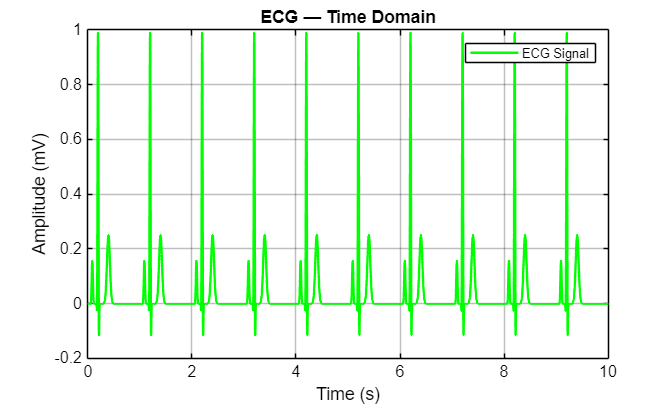

% Generate ECG signal
duration   = 10;
fs         = 1000;
beat_every = 1;

t   = 0 : 1/fs : duration;
tau = mod(t, beat_every);

a1 =  0.25;  b1 = 0.09;   c1 = 0.015;
a2 = -0.2;   b2 = 0.185;  c2 = 0.008;
a3 =  1.6;   b3 = 0.20;   c3 = 0.012;
a4 = -0.4;   b4 = 0.215;  c4 = 0.008;
a5 =  0.4;   b5 = 0.40;   c5 = 0.04;

scale = 1 / 1.6;

ecg = scale * ( a1 .* exp(-((tau - b1)./c1).^2) + ...
                a2 .* exp(-((tau - b2)./c2).^2) + ...
                a3 .* exp(-((tau - b3)./c3).^2) + ...
                a4 .* exp(-((tau - b4)./c4).^2) + ...
                a5 .* exp(-((tau - b5)./c5).^2) );

% ---- Package for Simulink ----
ecg_sim.time               = t';
ecg_sim.signals.values     = ecg';
ecg_sim.signals.dimensions = 1;

% ---- Plot: Time Domain ----
figure;
set(gcf, 'Color', 'w');
plot(t, ecg, 'g', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Amplitude (mV)');
ttl = title('ECG — Time Domain');
ttl.Color = 'k';
grid on;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd = legend('ECG Signal');
lgd.Color = 'w'; lgd.TextColor = 'k';
lgd.EdgeColor = 'k'; lgd.FontSize = 8;

## Generated ECG 

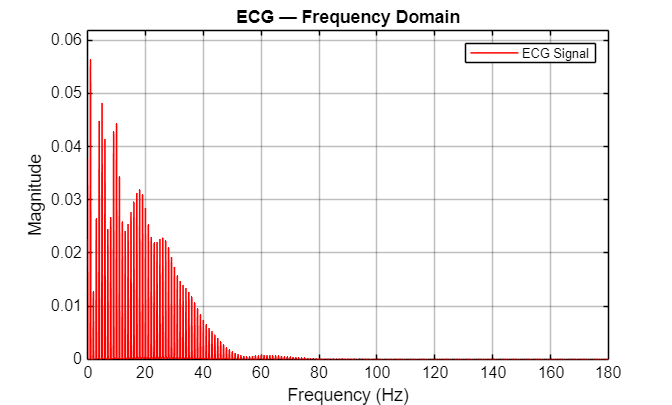

% ---- Frequency Analysis (FFT) ----
L  = length(ecg);
Y  = fft(ecg);
P2 = abs(Y / L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2 * P1(2:end-1);
f  = fs * (0:(floor(L/2))) / L;

% ---- Plot: Frequency Domain ----
figure;
set(gcf, 'Color', 'w');
plot(f, P1, 'r', 'LineWidth', 1.0);
ttl = title('ECG — Frequency Domain');
ttl.Color = 'k';
xlabel('Frequency (Hz)'); ylabel('Magnitude');
grid on;
xlim([0 180]); ylim([0 max(P1)*1.1]);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd = legend('ECG Signal');
lgd.Color = 'w'; lgd.TextColor = 'k';
lgd.EdgeColor = 'k'; lgd.FontSize = 8;

## Generated ECG "Noisy + Amplfied" 

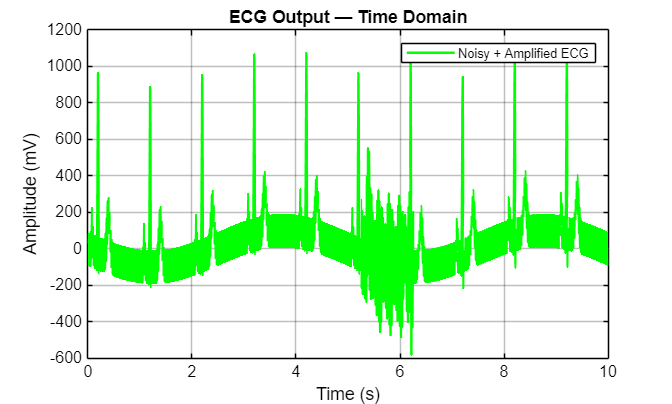

% ---- Extract data from Simulink timeseries ----
t_out   = out.ecg_amplified.Time;
ecg_out = out.ecg_amplified.Data;
ecg_out = ecg_out(:)';
fs_out  = 1 / mean(diff(t_out));

% ---- Time Domain ----
figure;
set(gcf, 'Color', 'w');
plot(t_out, ecg_out, 'g', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Amplitude (mV)');
ttl = title('ECG Output — Time Domain');
ttl.Color = 'k';
grid on;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd = legend('Noisy + Amplified ECG');
lgd.Color = 'w'; lgd.TextColor = 'k';
lgd.EdgeColor = 'k'; lgd.FontSize = 8;

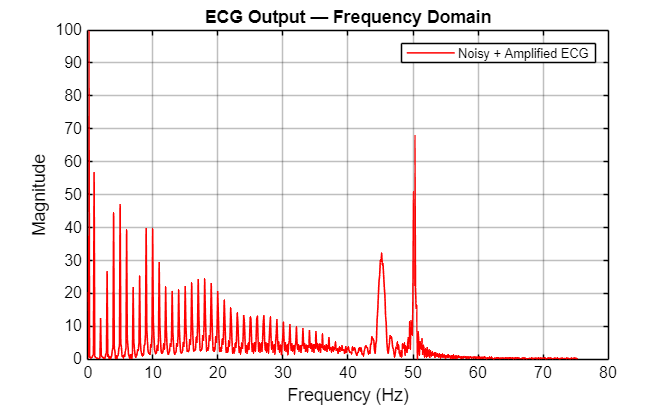


% ---- Frequency Domain ----
L  = length(ecg_out);
Y  = fft(ecg_out);
P2 = abs(Y / L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2 * P1(2:end-1);
f  = fs_out * (0:floor(L/2)) / L;

figure;
set(gcf, 'Color', 'w');
plot(f, P1, 'r', 'LineWidth', 1.0);
xlabel('Frequency (Hz)'); ylabel('Magnitude');
ttl = title('ECG Output — Frequency Domain');
ttl.Color = 'k';
grid on;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd = legend('Noisy + Amplified ECG');
lgd.Color = 'w'; lgd.TextColor = 'k';
lgd.EdgeColor = 'k'; lgd.FontSize = 8;

## ECG "Filtered"

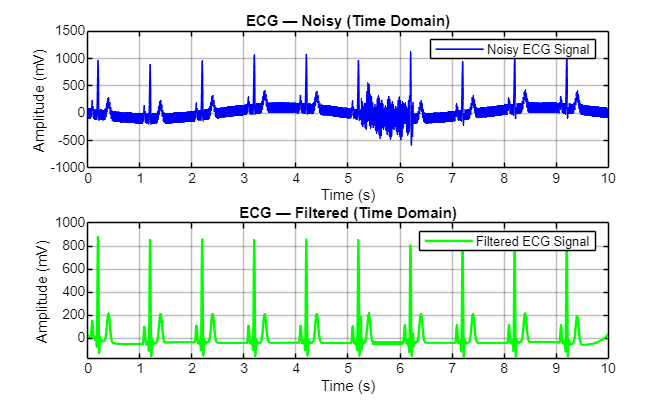

% ---- Extract Simulink output ----
t_out   = out.ecg_amplified.Time;
ecg_out = out.ecg_amplified.Data(:)';
fs_out  = 1 / mean(diff(t_out));

% ---- Filter 1: High-Pass ----
order_hp = 4; fc_hp = 0.5;
Wn_hp = fc_hp / (fs_out/2);
[b_hp, a_hp] = butter(order_hp, Wn_hp, 'high');
ecg_hp = filtfilt(b_hp, a_hp, ecg_out);

% ---- Filter 2: Notch ----
notch_freq = 50; bandwidth = 1;
Wn_notch = [notch_freq - bandwidth/2, notch_freq + bandwidth/2] / (fs_out/2);
[b_n, a_n] = butter(2, Wn_notch, 'stop');
ecg_notch = filtfilt(b_n, a_n, ecg_hp);

% ---- Filter 3: Low-Pass ----
order_lp = 4; fc_lp = 35;
Wn_lp = fc_lp / (fs_out/2);
[b_lp, a_lp] = butter(order_lp, Wn_lp, 'low');
ecg_clean = filtfilt(b_lp, a_lp, ecg_notch);

% ---- Plot: Time Domain (Noisy vs Filtered) ----
figure;
set(gcf, 'Color', 'w');

subplot(2,1,1);
plot(t_out, ecg_out, 'b', 'LineWidth', 1);
ttl1 = title('ECG — Noisy (Time Domain)');
ttl1.Color = 'k';
xlabel('Time (s)'); ylabel('Amplitude (mV)');
grid on;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd1 = legend('Noisy ECG Signal');
lgd1.Color = 'w'; lgd1.TextColor = 'k';
lgd1.EdgeColor = 'k'; lgd1.FontSize = 8;

subplot(2,1,2);
plot(t_out, ecg_clean, 'g', 'LineWidth', 1.5);
ttl2 = title('ECG — Filtered (Time Domain)');
ttl2.Color = 'k';
xlabel('Time (s)'); ylabel('Amplitude (mV)');
grid on;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd2 = legend('Filtered ECG Signal');
lgd2.Color = 'w'; lgd2.TextColor = 'k';
lgd2.EdgeColor = 'k'; lgd2.FontSize = 8;

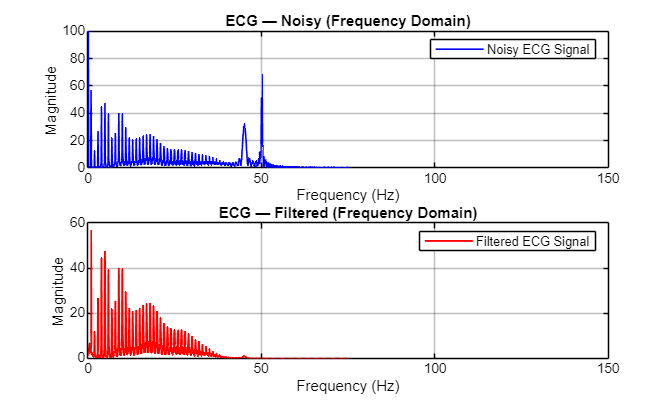


% ---- Frequency Domain Spectra ----
L = length(ecg_out);
f = fs_out * (0:floor(L/2)) / L;

P1_noisy = abs(fft(ecg_out)/L);
P1_noisy = P1_noisy(1:floor(L/2)+1);
P1_noisy(2:end-1) = 2*P1_noisy(2:end-1);

P1_clean = abs(fft(ecg_clean)/L);
P1_clean = P1_clean(1:floor(L/2)+1);
P1_clean(2:end-1) = 2*P1_clean(2:end-1);

% ---- Plot: Frequency Domain (Noisy vs Filtered) ----
figure;
set(gcf, 'Color', 'w');

subplot(2,1,1);
plot(f, P1_noisy, 'b', 'LineWidth', 1);
ttl1 = title('ECG — Noisy (Frequency Domain)');
ttl1.Color = 'k';
xlabel('Frequency (Hz)'); ylabel('Magnitude');
grid on; xlim([0 150]);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd1 = legend('Noisy ECG Signal');
lgd1.Color = 'w'; lgd1.TextColor = 'k';
lgd1.EdgeColor = 'k'; lgd1.FontSize = 8;

subplot(2,1,2);
plot(f, P1_clean, 'r', 'LineWidth', 1.2);
ttl2 = title('ECG — Filtered (Frequency Domain)');
ttl2.Color = 'k';
xlabel('Frequency (Hz)'); ylabel('Magnitude');
grid on; xlim([0 150]);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd2 = legend('Filtered ECG Signal');
lgd2.Color = 'w'; lgd2.TextColor = 'k';
lgd2.EdgeColor = 'k'; lgd2.FontSize = 8;

## Before and After

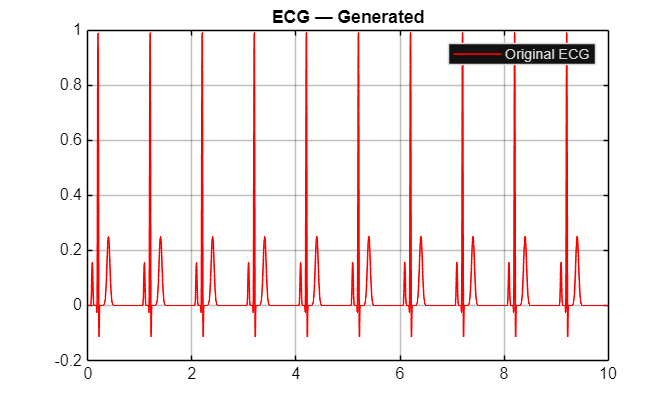

figure;
set(gcf, 'Color', 'w');
plot(t, ecg, 'r', 'LineWidth', 1);
legend('Original ECG');
ttl = title('ECG — Generated');
ttl.Color = 'k';
grid on;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');

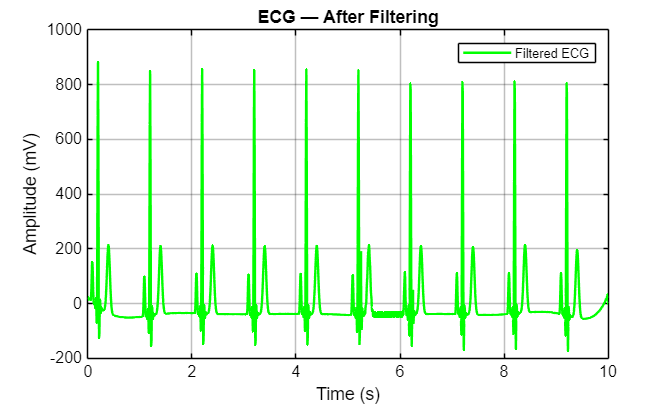

plot(t_out, ecg_clean, 'g', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Amplitude (mV)');
ttl = title('ECG — After Filtering');
ttl.Color = 'k';
grid on;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd = legend('Filtered ECG');
lgd.Color = 'w'; lgd.TextColor = 'k';
lgd.EdgeColor = 'k'; lgd.FontSize = 8;

## Heart beats & R-R Peaks Calculations

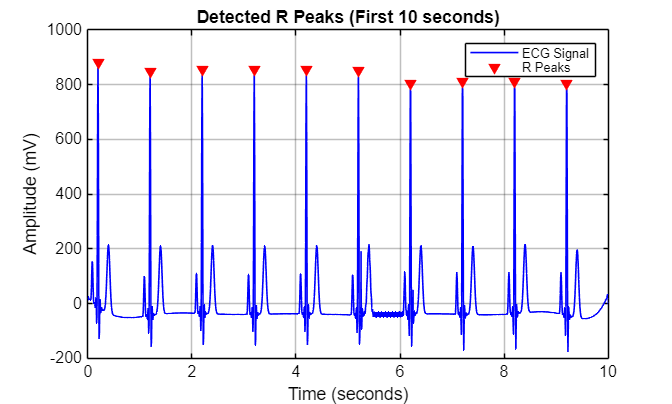

% ---- Setup ----
time_vector = t_out;
ecg_notch   = ecg_clean;
Fs          = fs_out;

tEnd  = 10;
idx10 = time_vector <= tEnd;
t10   = time_vector(idx10);
ecg10 = ecg_notch(idx10);

% ---- R Peak Detection ----
[pks, locs] = findpeaks(ecg10, ...
    'MinPeakDistance',   round(0.4*Fs), ...
    'MinPeakProminence', 0.25);

maxPeaks = 10;
[~, sort_idx] = sort(pks, 'descend');
top_idx  = sort(sort_idx(1:min(maxPeaks, end)));
pks  = pks(top_idx);
locs = locs(top_idx);

% ---- Plot: R Peaks ----
figure;
set(gcf, 'Color', 'w');
plot(t10, ecg10, 'b', 'LineWidth', 1);
hold on;
plot(t10(locs), pks, 'rv', 'MarkerFaceColor', 'r');
hold off;
xlabel('Time (seconds)'); ylabel('Amplitude (mV)');
ttl = title('Detected R Peaks (First 10 seconds)');
ttl.Color = 'k';
grid on;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
lgd = legend('ECG Signal', 'R Peaks');
lgd.Color = 'w'; lgd.TextColor = 'k';
lgd.EdgeColor = 'k'; lgd.FontSize = 8;


% ---- RR Intervals & Heart Rate ----
RR     = diff(t10(locs));
HR     = 60 ./ RR;
meanHR = mean(HR);

%% Display results
disp('--- Member 3 Results ---')

--- Member 3 Results ---


disp(['Number of R-peaks in 10s:  ', num2str(length(pks))])

Number of R-peaks in 10s:  10


disp(['RR Intervals (s):          ', num2str(RR(:)')])

RR Intervals (s):          1           1           1           1           1     0.99667           1           1           1


disp(['Mean Heart Rate (bpm):     ', num2str(meanHR)])

Mean Heart Rate (bpm):     60.0223
